This part is for analyzing the running vs resting experiment.

First I need to pull out one acquistion to do the fitting (although fitting is not important for my lifetime calculation of ACh sensor signal).

Then load the acquistion data and run the analysis.

filename='120821_m37_001_RvR_samepower';

datafile='continuous aquistion data_7.mat';
load(datafile);


timebin=1;
ch=1;

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);


The next session is to export the data into csv file for running the python analysis.

load([filename,'.mat'])

time_csv=[filename,'_time.csv'];
intensity_csv=[filename,'_intensity.csv'];
lft_fit_csv=[filename,'_tau_fitting.csv'];
lft_emp_csv=[filename,'_tau_emp.csv'];

csvwrite(time_csv,time);
csvwrite(intensity_csv,photoncount);
csvwrite(lft_fit_csv,tau_avg);
csvwrite(lft_emp_csv,tau_empTrunc);

This section is for 

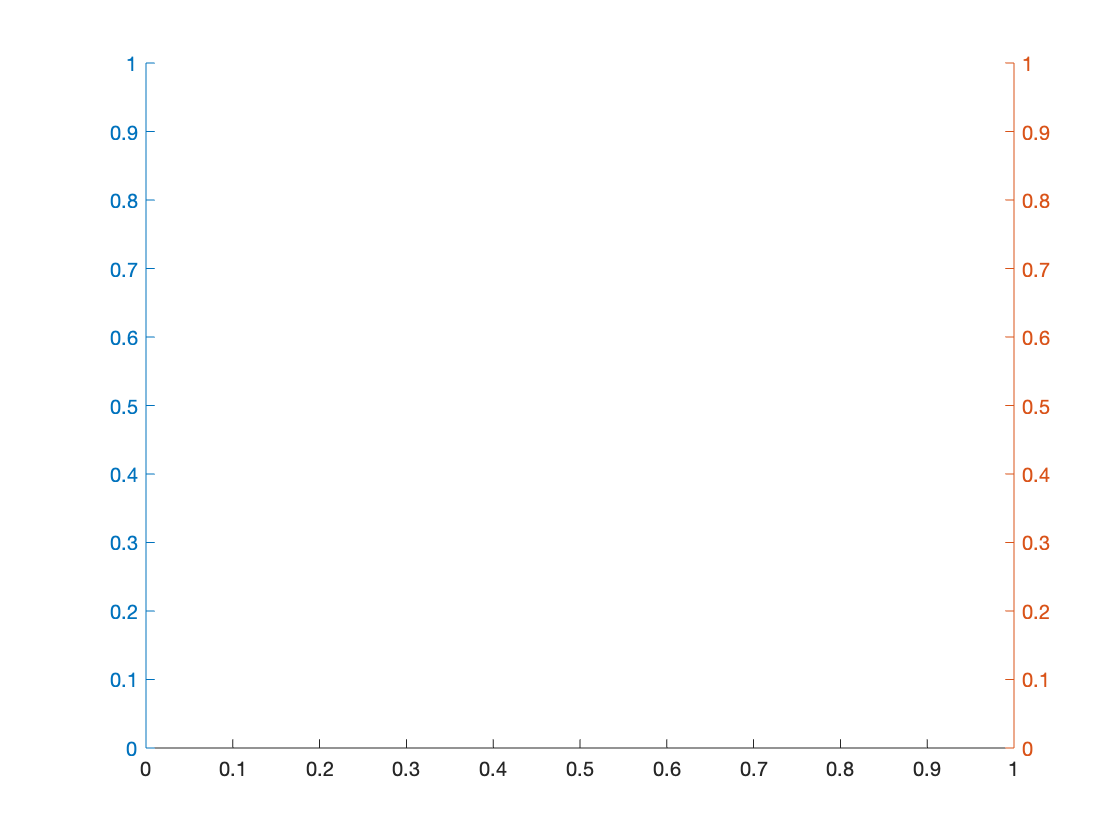

figure
yyaxis left

plot(time_from_bonsai, speed );

Unrecognized function or variable 'time_from_bonsai'.

yyaxis right
hold on
plot(time, tau_empTrunc);

figure
yyaxis left
plot(time_from_bonsai, speed );
yyaxis right
hold on
plot(time, photoncount);